# Estimate Multiple Linear Regression Coefficients

Load the `carsmall` data set. Identify weight and horsepower as predictors and mileage as the response.

load carsmall
x1 = Weight;
x2 = Horsepower;    % Contains NaN data
y = MPG;

Compute the regression coefficients for a linear model with an interaction term.

X = [ones(size(x1)) x1 x2 x1.*x2];
b = regress(y,X)    % Removes NaN data

b =          60.71
         -0.01
         -0.19
          0.00


Plot the data and the model.

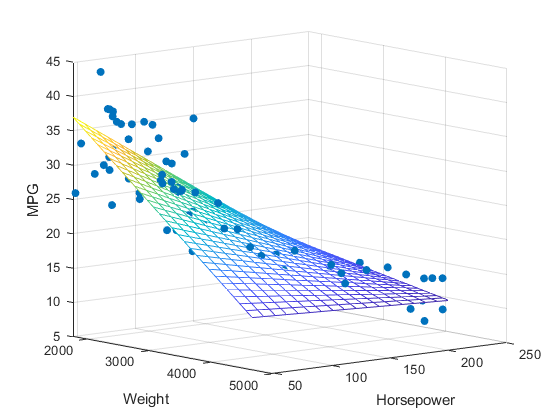

scatter3(x1,x2,y,'filled')
hold on
x1fit = min(x1):100:max(x1);
x2fit = min(x2):10:max(x2);
[X1FIT,X2FIT] = meshgrid(x1fit,x2fit);
YFIT = b(1) + b(2)*X1FIT + b(3)*X2FIT + b(4)*X1FIT.*X2FIT;
mesh(X1FIT,X2FIT,YFIT)
xlabel('Weight')
ylabel('Horsepower')
zlabel('MPG')
view(50,10)
hold off

*Copyright 2015 The MathWorks, Inc.*